# Outlier Removal

clear;clc
rng(42)

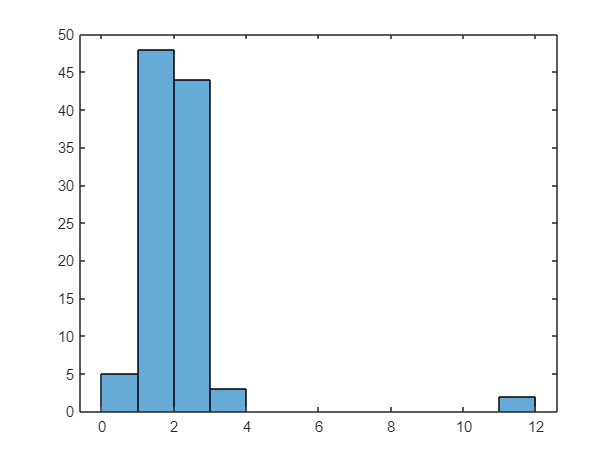

% Generating a dataset with outliers
X = [randn(100,1) * 0.5; 10;10]+2;
histogram(X)

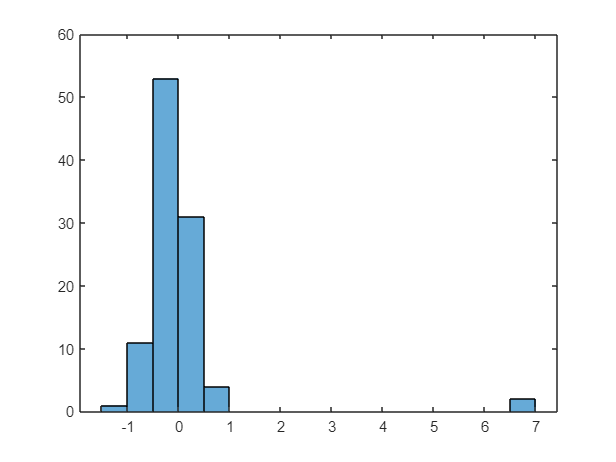

% Calculating the z-score of every sample in the dataset
z = (X-mean(X,1)) / std(X);

% Plotting the distribution of z
histogram(z)

Comments: most of the samples have z-scores less than 1.

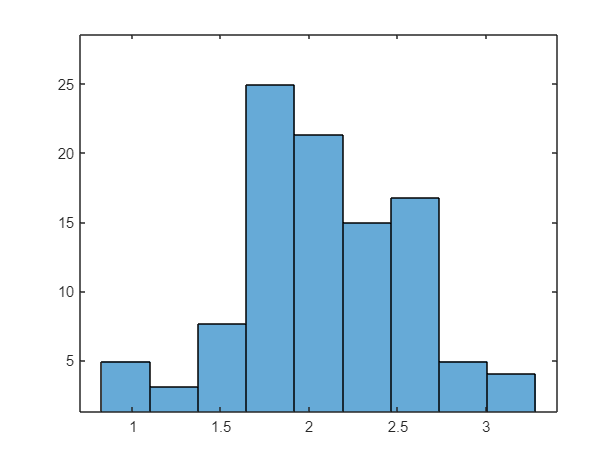

% Filtering out those samples having large z-scores
i_mem = []; % the indexes of which will be removed
for i = 1:size(z, 1)
    if z(i) >= 1 % the threshold could also be 2, depends on different situations
        i_mem = [i_mem, i];
    end
end
X(i_mem) = []; % Removing outliers
histogram(X)

Comment: outliers are filtered out.

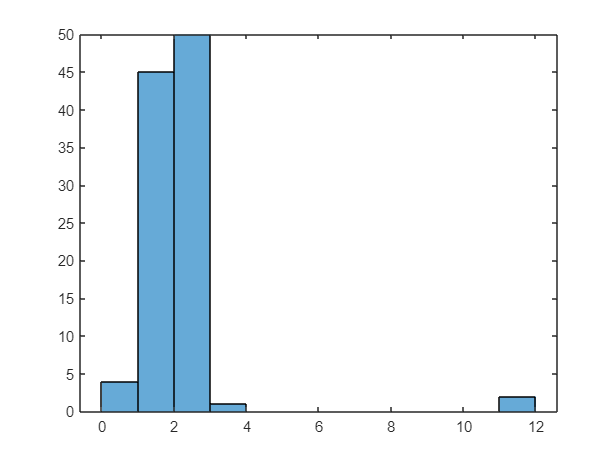

% Generating a dataset with outliers
X = [randn(100,1) * 0.5; 10;10]+2;
histogram(X)

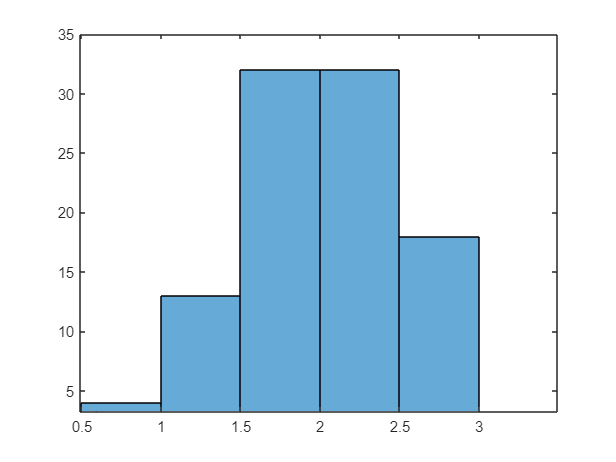

% Filtering out those samples lies outside the IQR
Q1 = prctile(X,25);
Q3 = prctile(X,75);
IQR = Q3 - Q1;
i_mem = []; % the indexes of which will be removed
for i = 1:size(X, 1)
    if X(i) >= Q3 + 1.5*IQR || X(i) <= Q1 - 1.5*IQR
        i_mem = [i_mem, i];
    end
end
X(i_mem) = []; % Removing outliers
histogram(X)

Comment: outliers are filtered out.